# Dati simulazione 

clear; close all; clc

T_sim = 60;

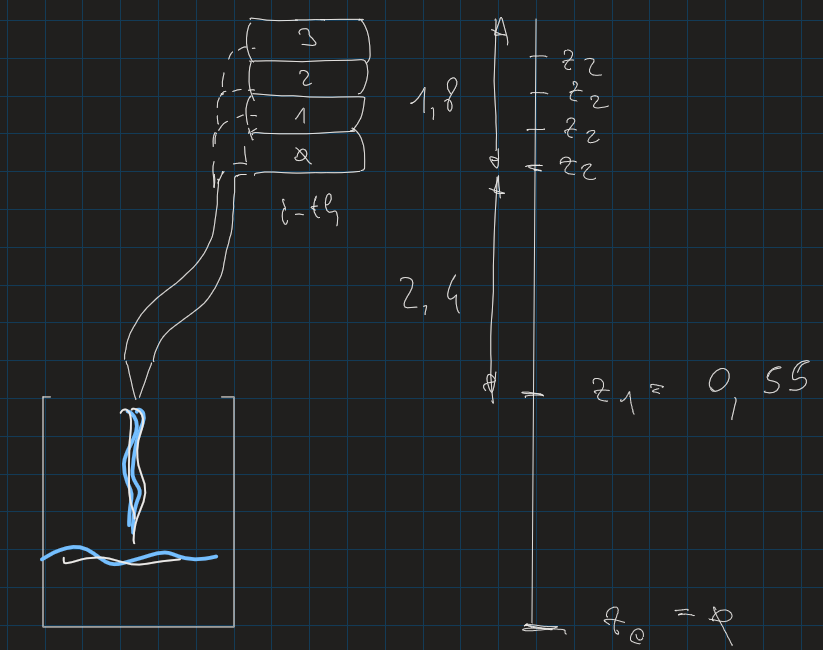

r_barile = 0.1784;            % [m]   raggio della base del barile 

rho_l = 1000;                 % [kg/m^3]   densità del liquido
g = 9.81;                     % [m/s^2]    acc. di gravità
gamma_l = rho_l * g;          % [N / m^3]  peso specifico del liquido


uscita ugello   1

z1 = 0.55;                    % [m]
p_atm = 101325;               % [Pa]
p1 = p_atm;                   % [Pa] pressione uscita dall'ugello
% v1 = incognita              % velocità appena uscito dall'ugello


pelo acqua serbatoio   2

i_th = 0;                     % [adim]  i-esimo serbatoio (in altezza)
z2 = z1+ 2.4 + i_th*(1.8/4);  % [m] 
dp_serbatoio = 100;           % [Pa]
p2 = p_atm + dp_serbatoio;    % [Pa] pressione pelo dell'acqua serbatoio
v2 = 0;                       % [m/s^2] velocità pelo dell'acqua serbatoio

% perdite
k_imbocco = 0.5;            
k_uscita = 0.89;







## Viscosità

Le **perdite di carico continue**, attribuibili alla viscosità, sono compendiate dalla nota formula di Darcy-Weisbach: 

[Perdite di carico nelle tubazioni (edutecnica.it)](https://www.edutecnica.it/macchine/carico/carico.htm)

$y_{c\;} =\lambda \;\frac{L}{d}\cdot \left(\frac{v^2 }{2g}\right)$                     se regime laminare   $\lambda =\frac{\;64}{\textrm{Re}}$             

L: lunghezza del tubo                                                 d: diametro del tubo

v: velocità del fluido                                                    g: accelerazione di gravità


$$\textrm{Re}=\frac{\;\rho \;v\;d}{\mu \;}$$


v:  velocità del flusso                                                    d: diametro del tubo

$\mu$: viscosità dinamica   $\left\lbrack \textrm{Pa}\cdot s\right\rbrack \;\left\lbrack N\cdot \frac{s}{m^2 }\right\rbrack \left\lbrack \frac{\;\textrm{kg}}{m\cdot s}\right\rbrack$          $\rho$: densità

L_tubo = 4.5;   % [m]
d_tubo = 0.01;  % [m]
A_tubo = pi * (d_tubo/2)^2;   % [m^2] sezione di passaggio nel tubo
% v_tubo          % dove ho tanta dispersione, da calcolare
mu_l = 0.89;   % [cP] 
mu_l = mu_l * 10^-3;   % [Pa/s]


c = 0.9;    % A1 = c*A   segione passaggio + grande sezione uscita ugello



altezza tappo - Apertura

theta_piccolo = deg2rad(60);           % [rad]
theta_grande  = deg2rad(30);           % [rad]
r_piccolo     = 0.005;                 % [m]                    
r_grande      = 0.01;                  % [m]
h_limite      = 0.01;                  % [m] altezza massiam oltre la quale si apre anche il grande

base_barile = pi * r_barile^2;  % [m^2]
m_to_kg = 0.1 * 1000;       % da altezza liquido nel barile in kg di liquido
kg_to_m = 10 * 0.001;       % da kg in altezza liquido nel barile

#### conversione

- base del barile: $0\ldotp 1\;m^2$

- 
$$1\;{\textrm{kg}}_{\;\textrm{acqua}} =0\ldotp 001\;m^3$$


m_to_kg = 0.1 * 1000;       % da altezza liquido nel barile in kg di liquido
kg_to_m = 10 * 0.001;       % da kg in altezza liquido nel barile

#### segnale di riferimento (step)

step_time = 5;
step_liq = 5;        % quanti litri voglio riempire

#### controllore proporzionale

k = 0.1;              % valore proporzionale del regolatore    2.4

#### condizioni iniziali

livello_0 = [0];    % altezza iniziale di tutti i liquidi mescolati

#### manovellismo   [www.docenti.unina.it](https://www.docenti.unina.it/webdocenti-be/allegati/materiale-didattico/669152)       

r = 0.02;       % [m]
l = 0.03;       % [m]
mu = l/r;       % da non confondere con mu_l viscosità del liquido

#### liquido nella vasca

tau_max = 5;                    % massimo ritardo  
L = 0.5;   